# PCA Test

Read a hyperspectral data into the workspace. 

hcube = imread('CROP1_47.tiff');

Compute the principal component bands of the hyperspectral data cube. Specify the number of principal components to extract as 5. By default, the function uses the singular value decomposition (SVD) method for extracting principal components.

reducedDataCube = hyperpca(hcube,5);

Display the first 10 spectral bands in input data cube.

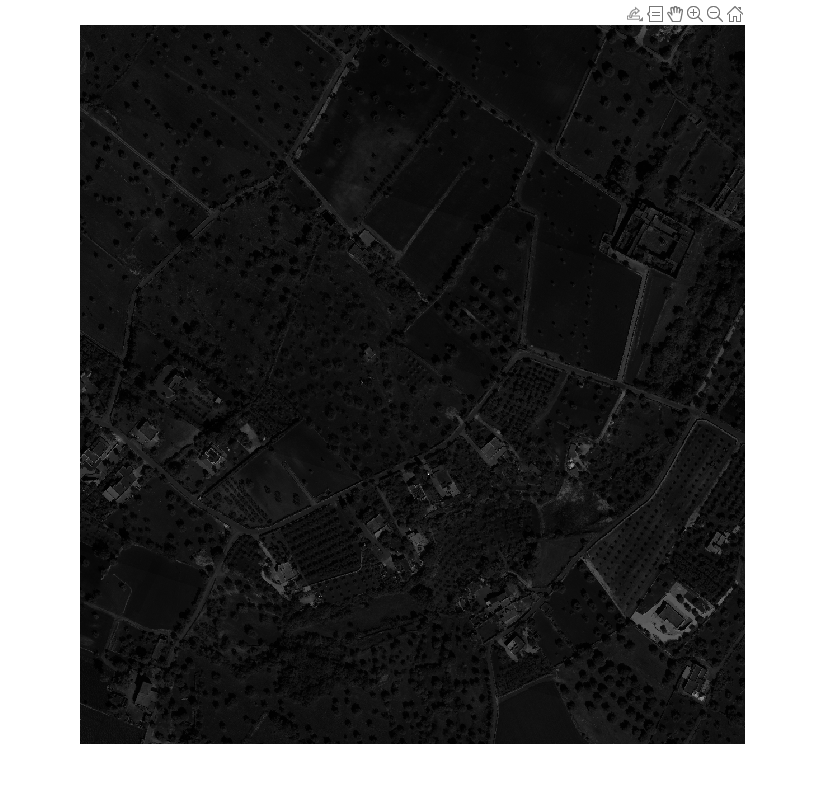

% We want to show the first image

img = squeeze(reducedDataCube(:,:,1)); % Extracting the first image
imshow(img,[]); % Visualize image

For the purpose of visualization, rescale the principal component values to lie in the range [0, 1]. Display all the principal component bands extracted from the data cube.

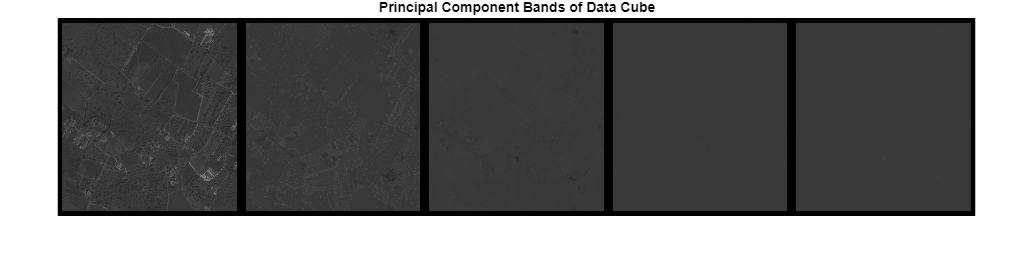

rescalePC = rescale(reducedDataCube,0,1);

figure
montage(rescalePC,'BorderSize',[10 10],'Size',[1 5]);
title('Principal Component Bands of Data Cube')